clc;
close all;
clear;

Storage =dir(fullfile("D:","Eng","Image-Despeckling","Testset","speckled","*.png"));
fprintf("No.of images in the speckled set: %d\n",numel(Storage));

No.of images in the speckled set: 348



Noisy_set  = "D:\Eng\Image-Despeckling\Noisy_Dataset_train\";
Clean_set =  "D:\Eng\Image-Despeckling\Dataset_train\";
Testset_noisy = "D:\Eng\Image-Despeckling\Testset\speckled";
Testset_clean = "D:\Eng\Image-Despeckling\Testset\cleaned";


input = imread("D:\Eng\Image-Despeckling\Testset\speckled\speckled3.png");
doub_img = im2double(input);
doub_gray = im2gray(doub_img);
input_img = im2gray(input);

I_hsv = rgb2hsv(input);
hueval = 10*mean(mean(I_hsv(:,:,1))); 
satval = 10*mean(mean(I_hsv(:,:,2)));
valval = 10*mean(mean(I_hsv(:,:,3))); % extracting hsv features of the image for it to act as a unique image signature

hueval = round(hueval,1);
satval = round(satval,1);
valval = round(valval,1);

hueval = uint8(hueval);
satval = uint8(satval);
valval = uint8(valval);

% file_to_read = fopen('speckled_vals.txt','r');
% A = fscanf(file_to_read,formatSpec);
% B = readtable('speckled_vals.txt','ReadVariableNames',true);
% B.Properties.VariableNames = {'Hue','Sat','Val'}; %This step writes all the hsv values in a text file 

% hue_val = (B(1,"Hue"));
% sat_val = (B(1,"Sat"));
% val_val = (B(1,"Val"));

% hue_val = table2array(hue_val);
% sat_val = table2array(sat_val);
% val_val = table2array(val_val);

formatSpec = '%d';
hsv_inputs = fopen("hsv_inputs.txt",'w');
fprintf(hsv_inputs,formatSpec,hueval,satval,valval); % writing hsv inputs to a buffer file 
disp("HSV values written...");

HSV values written...


% pred_file = fopen('predicted_kernel.txt','r');
% kernel_val_predicted = uint8(fscanf(pred_file,"%d"));
% kernel_val_predicted = double(kernel_val_predicted)

pred_f = readmatrix("pred_kernel.csv")

pred_f =      5     5     5     5     6     5     5     5


% despeckling using the predicted kernel value for lee filter

output_img1 = Leefilter(doub_img,pred_f(1));
output_img2 = Leefilter(doub_img,pred_f(2));
output_img3 = Leefilter(doub_img,pred_f(3));
output_img4 = Leefilter(doub_img,pred_f(4));
output_img5 = Leefilter(doub_img,pred_f(5));
output_img6 = Leefilter(doub_img,pred_f(6));
output_img7 = Leefilter(doub_img,pred_f(7));
output_img8 = Leefilter(doub_img,pred_f(8));


final_img1 = postpr(output_img1);
final_img2 = postpr(output_img2);
final_img3 = postpr(output_img3);
final_img4 = postpr(output_img4);
final_img5 = postpr(output_img5);
final_img6 = postpr(output_img6);
final_img7 = postpr(output_img7);
final_img8 = postpr(output_img8);

figure
subplot(3, 3, 1);
imshow(input_img);
title('Noisy Image');

subplot(3,3,2)
imshow(final_img1)
title("Logistic Regression")

subplot(3,3,3)
imshow(final_img2)
title("Decision Tree Classifier")

subplot(3,3,4)
imshow(final_img3)
title("Random Forest Classifier")

subplot(3,3,5)
imshow(final_img4)
title("Support Vector Classifier")

subplot(3,3,6)
imshow(final_img5)
title("Gaussian Naive Bayes Classifier")

subplot(3,3,7)
imshow(final_img6)
title("Multinomial Naive Bayes Classifier")

subplot(3,3,8)
imshow(final_img7)  
title("Bernouli Naive Bayes classifier")

subplot(3,3,9)
imshow(final_img8)
title("ADA Boost Classifier")

sgtitle("Lee filter ")

% CleanLocation = fullfile(Testset_clean,sprintf('output88.png'));
% imwrite(final_img,CleanLocation);

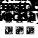

% outputs for the bilateral filter 
sigma_d = 1;       % Spatial standard deviation
sigma_r = 20;      % Intensity standard deviation

%filter_size = 5;   % Filter size

denoised_image1 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(1));
denoised_image2 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(2));
denoised_image3 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(3));
denoised_image4 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(4));
denoised_image5 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(5));
denoised_image6 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(6));
denoised_image7 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(7));
denoised_image8 = bilateral_filter(input_img, sigma_d, sigma_r, pred_f(8));

dn1 = uint8(denoised_image1);
dn2 = uint8(denoised_image2);
dn3 = uint8(denoised_image3);
dn4 = uint8(denoised_image4);
dn5 = uint8(denoised_image5);
dn6 = uint8(denoised_image6);
dn7 = uint8(denoised_image7);
dn8 = uint8(denoised_image8);

final_image1 = postpr(dn1);
final_image2 = postpr(dn2);
final_image3 = postpr(dn3);
final_image4 = postpr(dn4);
final_image5 = postpr(dn5);
final_image6 = postpr(dn6);
final_image7 = postpr(dn7);
final_image8 = postpr(dn8);

% Display the results
figure
subplot(331);
imshow(input_img);
title('Noisy Image');

subplot(332)
imshow(final_image1)
title("Logistic Regression")

subplot(333)
imshow(final_image2)
title("Decision Tree Classifier")

subplot(334)
imshow(final_image3)
title("Random Forest Classifier")

subplot(335)
imshow(final_image4)
title("Support Vector Classifier")

subplot(336)
imshow(final_image5)
title("Gaussian Naive Bayes Classifier")

subplot(337)
imshow(final_image6)
title("Multinomial Naive Bayes Classifier")

subplot(338)
imshow(final_image7)  
title("Bernouli Naive Bayes classifier")

subplot(339)
imshow(final_image8)
title("ADA Boost Classifier")

sgtitle("Bilateral filter")

% output of frost filter 
im_fi1 = frost_filter(doub_gray,[pred_f(1),pred_f(1)],0.1);
im_fi2 = frost_filter(doub_gray,[pred_f(2),pred_f(2)],0.1);
im_fi3 = frost_filter(doub_gray,[pred_f(3),pred_f(3)],0.1);
im_fi4 = frost_filter(doub_gray,[pred_f(4),pred_f(4)],0.1);
im_fi5 = frost_filter(doub_gray,[pred_f(5),pred_f(5)],0.1);
im_fi6 = frost_filter(doub_gray,[pred_f(6),pred_f(6)],0.1);
im_fi7 = frost_filter(doub_gray,[pred_f(7),pred_f(7)],0.1);
im_fi8 = frost_filter(doub_gray,[pred_f(8),pred_f(8)],0.1);

final1 = postpr(im_fi1);
final2 = postpr(im_fi2);
final3 = postpr(im_fi3);
final4 = postpr(im_fi4);
final5 = postpr(im_fi5);
final6 = postpr(im_fi6);
final7 = postpr(im_fi7);
final8 = postpr(im_fi8);


figure
subplot(331);
imshow(input_img);
title('Noisy Image');

subplot(332)
imshow(final1)
title("Logistic Regression")

subplot(333)
imshow(final2)
title("Decision Tree Classifier")

subplot(334)
imshow(final3)
title("Random Forest Classifier")

subplot(335)
imshow(final4)
title("Support Vector Classifier")

subplot(336)
imshow(final5)
title("Gaussian Naive Bayes Classifier")

subplot(337)
imshow(final6)
title("Multinomial Naive Bayes Classifier")

subplot(338)
imshow(final7)  
title("Bernouli Naive Bayes classifier")

subplot(339)
imshow(final8)
title("ADA Boost Classifier")

sgtitle("frost filter")

function lee_output = Leefilter(img,window_size)

img = double(img);
lee_output = img;
means = imfilter(img, fspecial('average', window_size), 'replicate');
sigmas = sqrt((img-means).^2/window_size^2);
sigmas = imfilter(sigmas, fspecial('average', window_size), 'replicate');

ENLs = (means./sigmas).^2;
sx2s = ((ENLs.*(sigmas).^2) - means.^2)./(ENLs + 1);
fbar = means + (sx2s.*(img-means)./(sx2s + (means.^2 ./ENLs)));
lee_output(means~=0) = fbar(means~=0);

end

function post_out = postpr(a)
    mf = ones(3, 3)/9;
    meanfilt = imfilter(a,mf);
    c =imsharpen(meanfilt,'Radius',3.5,'Amount',3.5);
    post_out = imfilter(c,mf);
end

function img_fi = frost_filter(img_n, win_size, Damp_fact)
    img_n = double(img_n);
    %Preallocate the Output Matrix
    img_fi = zeros(size(img_n));
    
    % making the window size odd if even
    if(mod(win_size,2)~=1)
        win_size=win_size+~mod(win_size,2);
    end
    
    mn = round((win_size-1)/2);
    
    %Padding with zeros around the border
    EImg = padarray(img_n,mn);
    
    
    [x,y]= meshgrid(-mn(1,1):mn(1,1),-mn(1,2):mn(1,2));
    S = sqrt(x.^2+y.^2);
    
    for i = 1:size(img_n,1)
        for j = 1:size(img_n,2)
            %Local Window
            K = EImg(i:i+win_size(1,1)-1,j:j+win_size(1,2)-1);
           
            %Mean value of the pixels in the local window
            meanV = mean(K(:));
           
            %variance of the pixels in the local window
            varV = var(K(:),1);
           
            %Weight for each pixel in the local window
            B =  Damp_fact*(varV/(meanV*meanV));
            Weigh = exp(-S.*B);
           
            % Filtering  
            img_fi(i,j) = sum(K(:).*Weigh(:))./sum(Weigh(:));
           
        end
    end

end


function denoised_image = bilateral_filter(image, sigma_d, sigma_r, filter_size)
    % Convert image to double precision
    image = double(image);
    
    % Create filter indices
    indices = -floor(filter_size/2):floor(filter_size/2);
    [X, Y] = meshgrid(indices, indices);
    
    % Compute the spatial Gaussian component
    G_spatial = exp(-(X.^2 + Y.^2) / (2 * sigma_d^2));
    
    % Initialize the denoised image
    denoised_image = zeros(size(image));
    
    % Iterate over the image
    [rows, cols] = size(image);
    for i = 1:rows
        for j = 1:cols
            % Extract the local region
            i_min = max(i - floor(filter_size/2), 1);
            i_max = min(i + floor(filter_size/2), rows);
            j_min = max(j - floor(filter_size/2), 1);
            j_max = min(j + floor(filter_size/2), cols);
            
            region = image(i_min:i_max, j_min:j_max);
            
            % Compute the intensity Gaussian component
            G_intensity = exp(-(region - image(i, j)).^2 / (2 * sigma_r^2));
            
            % Compute the bilateral filter response
            G_bilateral = G_spatial((i_min:i_max) - i + floor(filter_size/2) + 1, (j_min:j_max) - j + floor(filter_size/2) + 1) .* G_intensity;
            F_bilateral = G_bilateral .* region;
            
            % Update the denoised image
            denoised_image(i, j) = sum(F_bilateral(:)) / sum(G_bilateral(:));
        end
    end
    
    % Convert the denoised image back to the original data type
    denoised_image = cast(denoised_image, class(image));
end




